clc
clear
A = importdata("C:\Users\10571\Desktop\测试结果（盘轴）\A.txt");
B = importdata("C:\Users\10571\Desktop\测试结果（盘轴）\B.txt");
AB = importdata("C:\Users\10571\Desktop\测试结果（盘轴）\AB.txt");

iA = A(:,1) > 0;
iB = B(:,1) > 0;
iAB = AB(:,1) > 0;

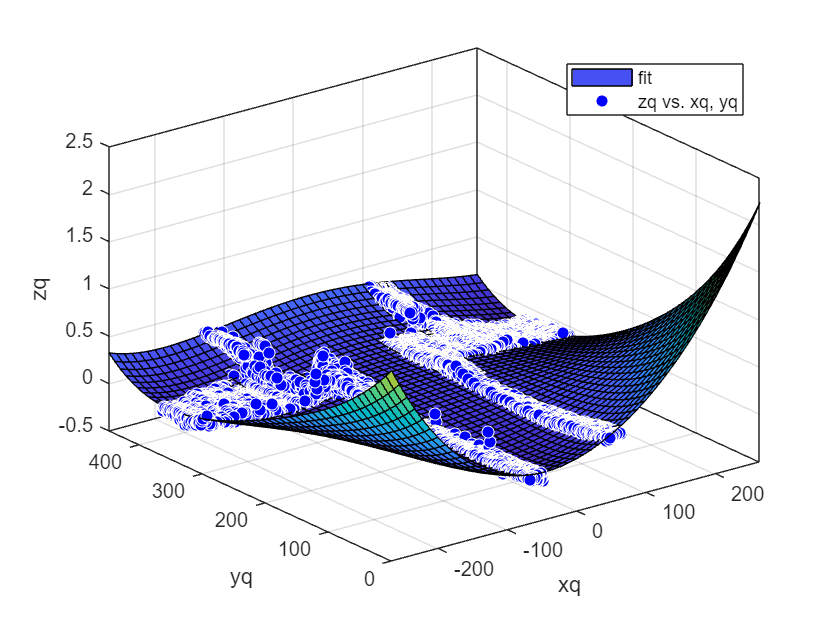

x0 = [A(iA,1);B(~iB,1)];
y0 = [A(iA,2);B(~iB,2)];
z0 = [A(iA,3);B(~iB,3)];
% x0 = [[A(iA,1);B(iB,1)];[B(~iB,1);A(~iA,1)]];
% y0 = [[A(iA,2);B(iB,2)];[B(~iB,2);A(~iA,2)]];
% z0 = [[A(iA,3);B(iB,3)];[B(~iB,3);A(~iA,3)]];
[y0,z0] = Re(y0,z0);
[x0,z0] = Re(x0,z0);
n0 = length(x0);
a0 = [x0,y0,z0,ones(n0,1)];
u0 = [-(max(x0)+min(x0))/2,-min(abs(y0)),-mean(z0)]; 
Tr0 = [1,0,0,u0(1);0,1,0,u0(2);0,0,1,u0(3);0,0,0,1];
A0 = a0*Tr0';
ImpData = [A0(:,1),A0(:,2),A0(:,3)];
%% 前处理
d = 2;%网格大小
[xq, yq, zq] = PreprocessDate(ImpData,d);
% [yq,zq] = Re(yq,zq);
% [xq,zq] = Re(xq,zq);
%% 拟合
n = 4;%拟合方程次数
[f  gof] = createFit(xq, yq, -zq, n);

P = coeffvalues(f);%多项式系数向量
s = dispf(P,n,n);
disp(s)

0.050185 + -0.003133*Y + 3.2435e-05*Y*Y + -1.1295e-07*Y*Y*Y + 1.3293e-10*Y*Y*Y*Y + 0.0020812*X + -1.3394e-05*X*Y + 3.5145e-08*X*Y*Y + -3.1483e-11*X*Y*Y*Y + 2.1685e-05*X*X + -1.4321e-07*X*X*Y + 1.8144e-10*X*X*Y*Y + -9.5536e-09*X*X*X + -1.5932e-12*X*X*X*Y + 5.657e-11*X*X*X*X 


disp(gof)

           sse: 31.3382
       rsquare: 0.6947
           dfe: 13345
    adjrsquare: 0.6944
          rmse: 0.0485



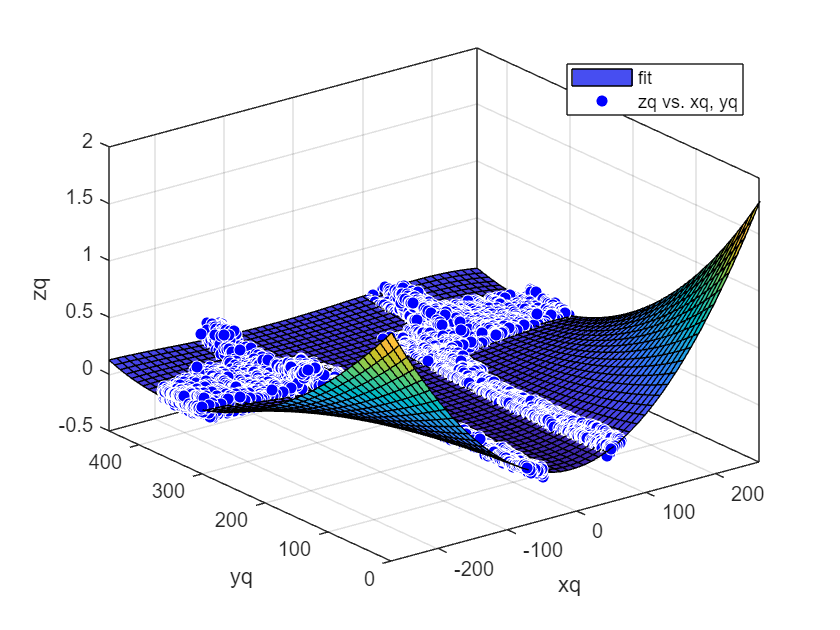

Xl = [-xq(xq<0);xq(xq>0)];
Yl = [yq(xq<0);yq(xq>0)];
Zl = [zq(xq<0);zq(xq>0)];
Xr = [-xq(xq>0);xq(xq<0)];
Yr = [yq(xq>0);yq(xq<0)];
Zr = [zq(xq>0);zq(xq<0)];
X = [Xl;Xr]; Y = [Yl;Yr]; Z = [0.27.*Zl+(1-0.27).*Zr;0.9.*Zl+0.1.*Zr];
[xq, yq, zq] = PreprocessDate([X,Y,Z],d);
% [yq,zq] = Re(yq,zq);
% [xq,zq] = Re(xq,zq);
%% 拟合
n = 4;%拟合方程次数
[f  gof] = createFit(xq, yq, -zq, n);

P = coeffvalues(f);%多项式系数向量
s = dispf(P,n,n);
disp(s)

-0.12029 + 5.744e-05*Y + 1.2452e-06*Y*Y + -1.9856e-09*Y*Y*Y + 1.9238e-12*Y*Y*Y*Y + 0.000428*X + -4.9606e-06*X*Y + 1.7448e-08*X*Y*Y + -1.7578e-11*X*Y*Y*Y + 2.6369e-05*X*X + -1.3178e-07*X*X*Y + 1.7207e-10*X*X*Y*Y + 2.0295e-09*X*X*X + -1.2818e-11*X*X*X*Y + -1.9587e-11*X*X*X*X 


disp(gof)

           sse: 28.0296
       rsquare: 0.3482
           dfe: 13793
    adjrsquare: 0.3476
          rmse: 0.0451

